f = @(x) 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2

f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


%f = @(x) (x - 2).^2 


[a, b, i] = expansion(f, 1, 1.1, 2, 1000)

a = 1.8000

b = 4.2000

i = 5

[a1, b1, i] = contraction(f, 0.5, a, b, 1000)

a1 = 1.8000

b1 = 2.4000

i = 3

figure;
hold on;
fplot(f);

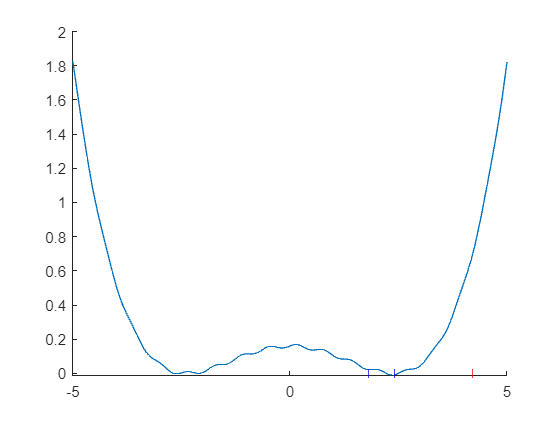

plot([a, b], [0, 0], '|r');
plot([a1, b1], [0, 0], '|b');

function [a, b, i] = contraction(f, beta, x0, x1, Nmax)
if f(x0) > f(x1)
    xtemp = x0;
    x0 = x1;
    x1 = xtemp;
end

i = 1;
xj = x1;

while f(x0) < f(xj)
    if i > Nmax
        a = -1*inf;
        b = inf;
        return;
    end
    xj = x0 + beta.^(i)*(x1 - x0);
    i = i +1;
end
a = x0;
b = xj;
return
end


function [a, b, i] = expansion(f, xzero, x1, alpha, Nmax)

x0 = xzero;
i = 0;
if f(x0) == f(x1)
    a = x0;
    b = x1;
    return
end

if f(x1) > f(x0)
    x1 = -1*(x1 - xzero) + xzero;
    if f(x1) == f(-1*(x1 - xzero) + xzero)
        a = -1*(x1 - xzero) + xzero;
        b = x1;
        return
    end
end

x2 = x1;
x1 = x0;
while f(x1) > f(x2)
    if i > Nmax
        a = -inf;
        b = inf;
        return 
    end
    i = i + 1;
    x0 = x1;
    x1 = x2;
    x2 = alpha * (x2 - xzero) + xzero;
end

if x0 < x2
    a = x0;
    b = x2;
    return
end
a = x2;
b = x0;
return;
end